maxLidarRange = 8;
mapResolution = 20;
maxNumScans = 1;
slamAlg = lidarSLAM(mapResolution, maxLidarRange, maxNumScans);
slamAlg.LoopClosureThreshold = 210;  
slamAlg.LoopClosureSearchRadius = 8;

scans = {};
for i = 1:numel(Angles)
    scans{end+1} = lidarScan(Ranges{i},deg2rad(Angles{i}));
end

for i=1:10
    [isScanAccepted, loopClosureInfo, optimizationInfo] = addScan(slamAlg, scans{i}, [0 0 0]);
    if isScanAccepted
        fprintf('Added scan %d \n', i);
    end
end

Added scan 1 
Added scan 2 
Added scan 3 
Added scan 4 
Added scan 5 
Added scan 6 
Added scan 7 
Added scan 8 
Added scan 9 
Added scan 10 


[~, Poses] = scansAndPoses(slamAlg

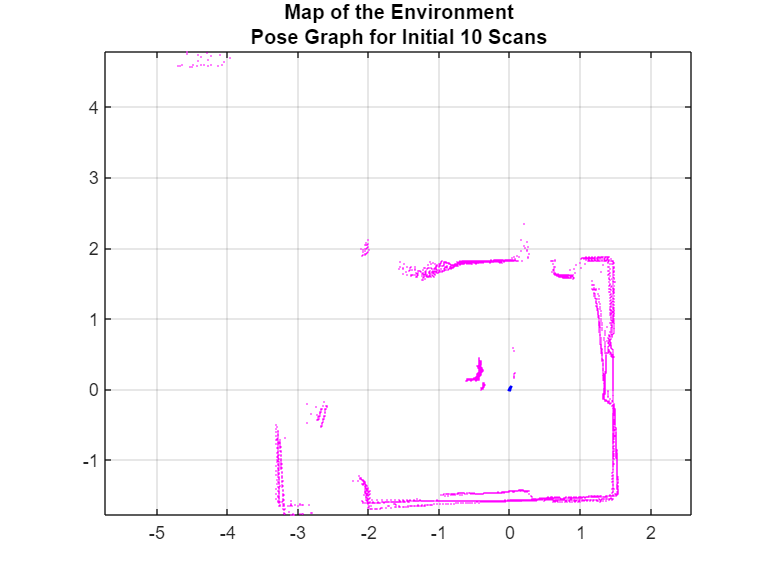

figure;
show(slamAlg);
title({'Map of the Environment','Pose Graph for Initial 10 Scans'});

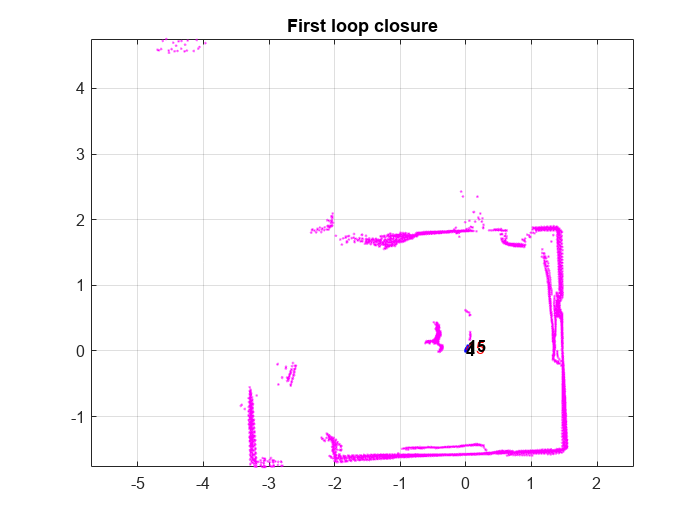

firstTimeLCDetected = false;

figure;
for i=10:length(scans)
    [isScanAccepted, loopClosureInfo, optimizationInfo] = addScan(slamAlg, scans{i}, [0 0 0]);
    if ~isScanAccepted
        continue;
    end
    % visualize the first detected loop closure, if you want to see the
    % complete map building process, remove the if condition below
    if optimizationInfo.IsPerformed && ~firstTimeLCDetected
        show(slamAlg, 'Poses', 'off');
        hold on;
        show(slamAlg.PoseGraph); 
        hold off;
        firstTimeLCDetected = true;
        drawnow
    end
end
title('First loop closure');

[scans, optimizedPoses]  = scansAndPoses(slamAlg);
map = buildMap(scans, optimizedPoses, mapResolution, maxLidarRange);

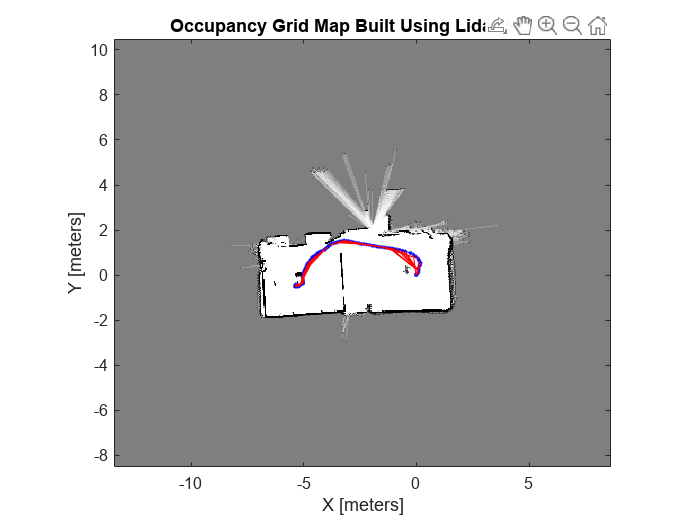

figure; 
show(map);
hold on
show(slamAlg.PoseGraph, 'IDs', 'off');
hold off
title('Occupancy Grid Map Built Using Lidar SLAM');